**Name : Krish Singh**

**Roll: AID25072**

**AID Semester 2**

## **LAB EXCERCISE 4**

*1. Using QR decomposition find the eigenvalues of a random integer symmetric matrix of order 15 and  verify the result using direct evaluation of eigenvalues.*

A=randi([0,9],15,15);
eig(A)

ans =   67.0020 + 0.0000i
   9.4079 + 4.6588i
   9.4079 - 4.6588i
  -2.0226 + 9.1917i
  -2.0226 - 9.1917i
  -9.5133 + 0.0000i
   2.4839 + 6.9090i
   2.4839 - 6.9090i
  -4.6354 + 5.0038i
  -4.6354 - 5.0038i
   7.4942 + 0.0000i
   5.8748 + 0.0000i
  -4.2129 + 0.0000i
  -1.5087 + 0.0000i
   1.3963 + 0.0000i


B=A;
for i=1:10
    [Q,R]=qr(B,0); %B=QR
    B=R*Q;
end
diag(B)

ans =    67.0020
    4.6970
   -3.1261
    8.5638
   -1.6480
    1.4488
    2.5318
    1.3245
   -1.5909
   -3.2889
   -0.0650
   -2.0117
    3.2752
    1.5746
   -1.6870


* 2. Generate a random integer 7 by 9 matrix A of rank 6.*

A=randi([0,9],7,6)*randi([0,9],6,9)

A =    122   163   143    86   122   168   116   114    87
   141   159    90   110   139   131   110   110    84
   120   186   169   109   132   183   135    86   117
    57    81    54    34    47    71    74    50    42
    88   120    93    69    80   121   107    52    82
   171   174   166   126   145   193   150    50   146
   192   185   164   130   162   168   143    70   133


*(a) Verify the rank of A is 6  *

if (rank(A)-6)<1e-10
    disp("Rank of A is 6")
else
    disp("Rank of A is not 6")
end

Rank of A is 6


*(b) Find the SVD of the matrix  *

[U,Z,V]=svd(A)

U =    -0.2023    0.2025   -0.3838   -0.0464    0.0973   -0.0133    0.0019   -0.1555    0.3943    0.0512   -0.4529    0.2865   -0.5350    0.0353    0.0447
   -0.2192   -0.4246    0.0872   -0.3638   -0.0627    0.0028    0.6198    0.1632    0.1024    0.0876   -0.2319    0.0444    0.1114   -0.3593   -0.0391
   -0.2763    0.3240    0.3838    0.0215    0.1874    0.0507    0.2579   -0.1087   -0.5718    0.2029   -0.0025    0.0657   -0.3660    0.0265   -0.2183
   -0.3257   -0.1771    0.2235    0.0075   -0.0795    0.1265   -0.0766   -0.6887    0.2253    0.1153   -0.0957   -0.0457    0.3117    0.2944   -0.2257
   -0.3219   -0.1294    0.0510    0.6105   -0.1765    0.0750   -0.1366    0.0821   -0.0456    0.3472   -0.0129    0.2981    0.1036   -0.3128    0.3492
   -0.2289    0.1615   -0.0446   -0.2902   -0.6090    0.4791    0.0289    0.1996    0.0132    0.0615    0.2134   -0.0324   -0.1220    0.2999    0.1971
   -0.1811    0.0743   -0.0317   -0.2797    0.2592    0.4326   -0.4960    0.1600   -0.2006

Z =    69.3072         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0   18.9499         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0   17.7036         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0   15.1016         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0   13.9918         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0   12.8755         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0   11.5907         0         0

V =    -0.3323   -0.4339   -0.3843   -0.1481    0.2097   -0.3737    0.0653   -0.3349    0.2253    0.0116   -0.1389    0.3955    0.0199   -0.0294    0.0613
   -0.3235    0.0692    0.2773    0.0577   -0.3540   -0.3628   -0.0209    0.0044   -0.3393    0.0429    0.3806    0.3304   -0.1077   -0.1218   -0.3944
   -0.1985    0.4234   -0.3265   -0.4600   -0.0596   -0.0499   -0.2985    0.3920    0.2293    0.2130    0.1489    0.1027   -0.1271    0.2490    0.0731
   -0.2603   -0.0181    0.2562    0.0808    0.2368    0.1216   -0.1387    0.1433    0.2643    0.2377   -0.4841   -0.0536   -0.0510    0.0182   -0.6186
   -0.2746    0.2031   -0.3244    0.2006   -0.0812    0.6872    0.1566   -0.1585    0.0686   -0.0762    0.1288    0.2911   -0.0981   -0.2815   -0.0927
   -0.2571   -0.1825   -0.1913   -0.1402    0.1523    0.0694   -0.5511   -0.1265   -0.2570   -0.3715    0.1439   -0.4638   -0.0991   -0.1656   -0.1396
   -0.2048   -0.1151    0.2831    0.2339    0.1831    0.1448   -0.4458   -0.0237   -0.0354

Z=svd(A)

Z =    69.3072
   18.9499
   17.7036
   15.1016
   13.9918
   12.8755
   11.5907
    9.0660
    7.5270
    5.9898
    5.7278
    4.0939
    2.6920
    2.1150
    0.1524


* (c) Using SVD find an orthonormal basis for all the fundamental subspaces of the matrix A *

[U,Z,V]=svd(A)

U =    -0.2023    0.2025   -0.3838   -0.0464    0.0973   -0.0133    0.0019   -0.1555    0.3943    0.0512   -0.4529    0.2865   -0.5350    0.0353    0.0447
   -0.2192   -0.4246    0.0872   -0.3638   -0.0627    0.0028    0.6198    0.1632    0.1024    0.0876   -0.2319    0.0444    0.1114   -0.3593   -0.0391
   -0.2763    0.3240    0.3838    0.0215    0.1874    0.0507    0.2579   -0.1087   -0.5718    0.2029   -0.0025    0.0657   -0.3660    0.0265   -0.2183
   -0.3257   -0.1771    0.2235    0.0075   -0.0795    0.1265   -0.0766   -0.6887    0.2253    0.1153   -0.0957   -0.0457    0.3117    0.2944   -0.2257
   -0.3219   -0.1294    0.0510    0.6105   -0.1765    0.0750   -0.1366    0.0821   -0.0456    0.3472   -0.0129    0.2981    0.1036   -0.3128    0.3492
   -0.2289    0.1615   -0.0446   -0.2902   -0.6090    0.4791    0.0289    0.1996    0.0132    0.0615    0.2134   -0.0324   -0.1220    0.2999    0.1971
   -0.1811    0.0743   -0.0317   -0.2797    0.2592    0.4326   -0.4960    0.1600   -0.2006

Z =    69.3072         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0   18.9499         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0   17.7036         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0   15.1016         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0   13.9918         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0   12.8755         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0   11.5907         0         0

V =    -0.3323   -0.4339   -0.3843   -0.1481    0.2097   -0.3737    0.0653   -0.3349    0.2253    0.0116   -0.1389    0.3955    0.0199   -0.0294    0.0613
   -0.3235    0.0692    0.2773    0.0577   -0.3540   -0.3628   -0.0209    0.0044   -0.3393    0.0429    0.3806    0.3304   -0.1077   -0.1218   -0.3944
   -0.1985    0.4234   -0.3265   -0.4600   -0.0596   -0.0499   -0.2985    0.3920    0.2293    0.2130    0.1489    0.1027   -0.1271    0.2490    0.0731
   -0.2603   -0.0181    0.2562    0.0808    0.2368    0.1216   -0.1387    0.1433    0.2643    0.2377   -0.4841   -0.0536   -0.0510    0.0182   -0.6186
   -0.2746    0.2031   -0.3244    0.2006   -0.0812    0.6872    0.1566   -0.1585    0.0686   -0.0762    0.1288    0.2911   -0.0981   -0.2815   -0.0927
   -0.2571   -0.1825   -0.1913   -0.1402    0.1523    0.0694   -0.5511   -0.1265   -0.2570   -0.3715    0.1439   -0.4638   -0.0991   -0.1656   -0.1396
   -0.2048   -0.1151    0.2831    0.2339    0.1831    0.1448   -0.4458   -0.0237   -0.0354

r=rank(A)

r = 15

CS=U(:,1:r)

CS =    -0.2023    0.2025   -0.3838   -0.0464    0.0973   -0.0133    0.0019   -0.1555    0.3943    0.0512   -0.4529    0.2865   -0.5350    0.0353    0.0447
   -0.2192   -0.4246    0.0872   -0.3638   -0.0627    0.0028    0.6198    0.1632    0.1024    0.0876   -0.2319    0.0444    0.1114   -0.3593   -0.0391
   -0.2763    0.3240    0.3838    0.0215    0.1874    0.0507    0.2579   -0.1087   -0.5718    0.2029   -0.0025    0.0657   -0.3660    0.0265   -0.2183
   -0.3257   -0.1771    0.2235    0.0075   -0.0795    0.1265   -0.0766   -0.6887    0.2253    0.1153   -0.0957   -0.0457    0.3117    0.2944   -0.2257
   -0.3219   -0.1294    0.0510    0.6105   -0.1765    0.0750   -0.1366    0.0821   -0.0456    0.3472   -0.0129    0.2981    0.1036   -0.3128    0.3492
   -0.2289    0.1615   -0.0446   -0.2902   -0.6090    0.4791    0.0289    0.1996    0.0132    0.0615    0.2134   -0.0324   -0.1220    0.2999    0.1971
   -0.1811    0.0743   -0.0317   -0.2797    0.2592    0.4326   -0.4960    0.1600   -0.200

RS=V(:,1:r)

RS =    -0.3323   -0.4339   -0.3843   -0.1481    0.2097   -0.3737    0.0653   -0.3349    0.2253    0.0116   -0.1389    0.3955    0.0199   -0.0294    0.0613
   -0.3235    0.0692    0.2773    0.0577   -0.3540   -0.3628   -0.0209    0.0044   -0.3393    0.0429    0.3806    0.3304   -0.1077   -0.1218   -0.3944
   -0.1985    0.4234   -0.3265   -0.4600   -0.0596   -0.0499   -0.2985    0.3920    0.2293    0.2130    0.1489    0.1027   -0.1271    0.2490    0.0731
   -0.2603   -0.0181    0.2562    0.0808    0.2368    0.1216   -0.1387    0.1433    0.2643    0.2377   -0.4841   -0.0536   -0.0510    0.0182   -0.6186
   -0.2746    0.2031   -0.3244    0.2006   -0.0812    0.6872    0.1566   -0.1585    0.0686   -0.0762    0.1288    0.2911   -0.0981   -0.2815   -0.0927
   -0.2571   -0.1825   -0.1913   -0.1402    0.1523    0.0694   -0.5511   -0.1265   -0.2570   -0.3715    0.1439   -0.4638   -0.0991   -0.1656   -0.1396
   -0.2048   -0.1151    0.2831    0.2339    0.1831    0.1448   -0.4458   -0.0237   -0.035

NS=V(:,r+1:end)


NS =

  15×0 empty double matrix



LNS=U(:,r+1:end)


LNS =

  15×0 empty double matrix



%can also be done simply by:
CS=orth(A)

CS =    -0.2023    0.2025   -0.3838   -0.0464    0.0973   -0.0133    0.0019   -0.1555    0.3943    0.0512   -0.4529    0.2865   -0.5350    0.0353    0.0447
   -0.2192   -0.4246    0.0872   -0.3638   -0.0627    0.0028    0.6198    0.1632    0.1024    0.0876   -0.2319    0.0444    0.1114   -0.3593   -0.0391
   -0.2763    0.3240    0.3838    0.0215    0.1874    0.0507    0.2579   -0.1087   -0.5718    0.2029   -0.0025    0.0657   -0.3660    0.0265   -0.2183
   -0.3257   -0.1771    0.2235    0.0075   -0.0795    0.1265   -0.0766   -0.6887    0.2253    0.1153   -0.0957   -0.0457    0.3117    0.2944   -0.2257
   -0.3219   -0.1294    0.0510    0.6105   -0.1765    0.0750   -0.1366    0.0821   -0.0456    0.3472   -0.0129    0.2981    0.1036   -0.3128    0.3492
   -0.2289    0.1615   -0.0446   -0.2902   -0.6090    0.4791    0.0289    0.1996    0.0132    0.0615    0.2134   -0.0324   -0.1220    0.2999    0.1971
   -0.1811    0.0743   -0.0317   -0.2797    0.2592    0.4326   -0.4960    0.1600   -0.200

RS=orth(A')

RS =    -0.3323   -0.4339    0.3843   -0.1481   -0.2097   -0.3737    0.0653    0.3349   -0.2253   -0.0116   -0.1389    0.3955    0.0199   -0.0294   -0.0613
   -0.3235    0.0692   -0.2773    0.0577    0.3540   -0.3628   -0.0209   -0.0044    0.3393   -0.0429    0.3806    0.3304   -0.1077   -0.1218    0.3944
   -0.1985    0.4234    0.3265   -0.4600    0.0596   -0.0499   -0.2985   -0.3920   -0.2293   -0.2130    0.1489    0.1027   -0.1271    0.2490   -0.0731
   -0.2603   -0.0181   -0.2562    0.0808   -0.2368    0.1216   -0.1387   -0.1433   -0.2643   -0.2377   -0.4841   -0.0536   -0.0510    0.0182    0.6186
   -0.2746    0.2031    0.3244    0.2006    0.0812    0.6872    0.1566    0.1585   -0.0686    0.0762    0.1288    0.2911   -0.0981   -0.2815    0.0927
   -0.2571   -0.1825    0.1913   -0.1402   -0.1523    0.0694   -0.5511    0.1265    0.2570    0.3715    0.1439   -0.4638   -0.0991   -0.1656    0.1396
   -0.2048   -0.1151   -0.2831    0.2339   -0.1831    0.1448   -0.4458    0.0237    0.035

NS=null(A)


NS =

  15×0 empty double matrix



LNS=null(A')


LNS =

  15×0 empty double matrix



* (d) Verify the results obtained in (c) by checking the orthogonality of RS & NS and CS & LNS. *

if norm(RS'*NS)<1e-10
    disp("Row Space is orthogonal to Null space")
else
    disp("Row Space is not orthonormal to Null space")
end

Row Space is orthogonal to Null space


if norm(CS'*LNS)<1e-10
    disp("CS is orthogonal to Left Null space")
else
    disp("Column Space is not orthinormal to Null Space")
end

CS is orthogonal to Left Null space


*(e) Find the singular values of A *

Svalue=diag(Z)

Svalue =    69.3072
   18.9499
   17.7036
   15.1016
   13.9918
   12.8755
   11.5907
    9.0660
    7.5270
    5.9898
    5.7278
    4.0939
    2.6920
    2.1150
    0.1524


*(f) Find the sum of square of the singular values of A using Frobenious norm. *

ss=Z.^2

ss = 1.0e+03 *

    4.8035         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.3591         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3134         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0    0.2281         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0    0.1958         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0    0.1658         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0    0.1343        

sum(ss)

ans = 1.0e+03 *

    4.8035    0.3591    0.3134    0.2281    0.1958    0.1658    0.1343    0.0822    0.0567    0.0359    0.0328    0.0168    0.0072    0.0045    0.0000


*(g) Write a MATLAB code to obtain the singular values of A without using the command ‘svd’. *

ATA=A'*A;
singvals=sqrt(abs(eig(ATA)))

singvals =     0.1524
    2.1150
    2.6920
    4.0939
    5.7278
    5.9898
    7.5270
    9.0660
   11.5907
   12.8755
   13.9918
   15.1016
   17.7036
   18.9499
   69.3072


* (h) Find the polar decomposition of the matrix*

[U,Z,V]=svd(A);
Q=U*V'

Q =     0.4681   -0.2336    0.3493    0.2664    0.3064   -0.1500   -0.2247    0.0289    0.0676   -0.1302    0.3777   -0.1501    0.2057   -0.3693   -0.0147
    0.3333   -0.0038   -0.2091    0.1504    0.0281   -0.2623   -0.1933   -0.0392    0.3794    0.4453   -0.3414    0.4358    0.1738    0.0698   -0.1737
   -0.2475    0.4747   -0.1209    0.2142    0.1116   -0.0577    0.0022    0.1838   -0.2889    0.2252    0.3240    0.4123    0.1227   -0.3540    0.2320
    0.2908    0.0329   -0.2610    0.3192    0.0614    0.0568    0.1706    0.2679   -0.0090    0.1353    0.3969   -0.0572   -0.5453    0.3593   -0.1758
    0.0977    0.1962   -0.1820   -0.0198    0.3006   -0.2103    0.7047    0.1096    0.2528   -0.0455   -0.0956   -0.2887    0.3098   -0.0232    0.1422
   -0.3436    0.0657    0.4931   -0.2334    0.3271   -0.0677   -0.0345    0.0316    0.4630    0.3572    0.1660   -0.0033   -0.2689    0.1195    0.1011
   -0.1473   -0.3123    0.1548    0.3779    0.1410    0.4955    0.2636   -0.1761   -0.2117

S=V*Z*V'

S =    18.7834    5.2010    3.4212    4.5424    3.9586    7.7930    2.8688    6.4085    6.0462    3.5686    1.8763    5.0370    3.8188    5.8664    5.6494
    5.2010   14.4494    3.5193    3.7438    2.7390    3.8403    5.2549    6.1465    6.6359    4.2685    7.1564    3.8349    6.3584    7.6419    3.4810
    3.4212    3.5193   14.7339    2.4506    4.5488    4.3938    0.4587    4.3680    0.4028    3.2857    2.3992    2.1281    4.7594    4.0741   -0.1974
    4.5424    3.7438    2.4506    9.6300    3.6239    3.6784    6.8779    2.7766    4.4147    2.6517    5.7264    5.2843    5.3418    5.7708    3.8544
    3.9586    2.7390    4.5488    3.6239   15.8712    4.2037    2.8825    6.7910    3.4563    3.2971    4.2873    2.5394    3.6531    6.1355    5.2321
    7.7930    3.8403    4.3938    3.6784    4.2037   12.6190    4.8237    2.9263    3.4326    3.6857    3.1314    2.4969    2.7394    4.6632    4.2762
    2.8688    5.2549    0.4587    6.8779    2.8825    4.8237   10.3606    1.7563    3.0574

check=Q*S

check =     8.0000    1.0000    7.0000    4.0000    7.0000    3.0000   -0.0000    6.0000    1.0000    1.0000    4.0000    1.0000    5.0000    3.0000    2.0000
    9.0000    4.0000   -0.0000    4.0000    2.0000    1.0000   -0.0000    2.0000    9.0000    8.0000   -0.0000    9.0000    2.0000    5.0000    3.0000
    1.0000    9.0000    2.0000    6.0000    5.0000    2.0000    5.0000    6.0000    0.0000    5.0000    9.0000    9.0000    7.0000    5.0000    4.0000
    9.0000    7.0000   -0.0000    7.0000    6.0000    6.0000    7.0000    6.0000    7.0000    5.0000    9.0000    5.0000    1.0000    8.0000    2.0000
    6.0000    9.0000   -0.0000    7.0000    8.0000    4.0000    9.0000    7.0000    8.0000    1.0000    4.0000    0.0000    6.0000    7.0000    8.0000
    0.0000    6.0000    8.0000    2.0000    9.0000    3.0000    1.0000    4.0000    8.0000    8.0000    4.0000    2.0000    1.0000    6.0000    1.0000
    2.0000   -0.0000    6.0000    6.0000    5.0000    8.0000    5.0000   -0.0000    0.

*(i) Find A+ , the pseudo-inverse of A and show the decomposition of it  *

zplus=pinv(Z)

zplus =     0.0144         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.0528         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.0565         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0    0.0662         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0    0.0715         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0    0.0777         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0    0.0863         0      

Aplus=V*zplus*U'

Aplus =     0.0768    0.0121   -0.1090   -0.0668    0.1627    0.0374   -0.0359    0.2643    0.0278   -0.0778   -0.1714   -0.0797    0.0216   -0.1016    0.0389
   -0.1273    0.1016    0.6123    0.5379   -0.8553   -0.5093    0.0641   -1.6700   -0.0309    0.6207    0.8756    0.1563   -0.2995    0.9817   -0.1022
    0.0666   -0.0731   -0.1050   -0.1163    0.1299    0.1655   -0.0549    0.2953    0.0235   -0.1304   -0.2226    0.0244    0.0436   -0.1229    0.0244
   -0.1267    0.1744    0.8858    0.9283   -1.4068   -0.8144    0.2045   -2.6406   -0.0839    0.8385    1.3913    0.3839   -0.5001    1.4348   -0.1799
    0.0116    0.0612    0.1442    0.0954   -0.1496   -0.1279    0.0413   -0.4022   -0.0674    0.1801    0.2397   -0.0559   -0.0427    0.2501   -0.0235
   -0.0780    0.0150    0.1959    0.1736   -0.3532   -0.2005    0.0936   -0.5615   -0.0417    0.2861    0.3664    0.0823   -0.0393    0.2699   -0.0704
    0.0700   -0.1042   -0.6415   -0.6235    1.0854    0.5364   -0.0757    1.8271    0.

check=pinv(A)

check =     0.0768    0.0121   -0.1090   -0.0668    0.1627    0.0374   -0.0359    0.2643    0.0278   -0.0778   -0.1714   -0.0797    0.0216   -0.1016    0.0389
   -0.1273    0.1016    0.6123    0.5379   -0.8553   -0.5093    0.0641   -1.6700   -0.0309    0.6207    0.8756    0.1563   -0.2995    0.9817   -0.1022
    0.0666   -0.0731   -0.1050   -0.1163    0.1299    0.1655   -0.0549    0.2953    0.0235   -0.1304   -0.2226    0.0244    0.0436   -0.1229    0.0244
   -0.1267    0.1744    0.8858    0.9283   -1.4068   -0.8144    0.2045   -2.6406   -0.0839    0.8385    1.3913    0.3839   -0.5001    1.4348   -0.1799
    0.0116    0.0612    0.1442    0.0954   -0.1496   -0.1279    0.0413   -0.4022   -0.0674    0.1801    0.2397   -0.0559   -0.0427    0.2501   -0.0235
   -0.0780    0.0150    0.1959    0.1736   -0.3532   -0.2005    0.0936   -0.5615   -0.0417    0.2861    0.3664    0.0823   -0.0393    0.2699   -0.0704
    0.0700   -0.1042   -0.6415   -0.6235    1.0854    0.5364   -0.0757    1.8271    0.

*3. Find the polar decomposition (A=QS) of the matrix 𝐴=[ 9 3 ; 4 5 ]. Verify that Q is an orthogonal matrix  and using the graph of the surface 𝑓(𝒙)=𝒙𝑇𝑺𝒙, verify that S is a positive definite matrix. *

A=[9 3 ; 4 5];
[U,Z,V]=svd(A);
Q=U*V';
S=V*Z*V';
disp(S);

    9.2621    3.3486
    3.3486    4.7736



check=Q*S

check =     9.0000    3.0000
    4.0000    5.0000


ocheck=Q'*Q

ocheck =     1.0000         0
         0    1.0000


if norm(ocheck - eye(size(Q)))<1e-10
    disp("Q is orthogonal")
else
    disp("Q is not orthogonal")
end

Q is orthogonal


if norm(S-S')<1e-10
    disp("S is symmetric")
else
    disp("S is NOT symmetric")
end

S is symmetric


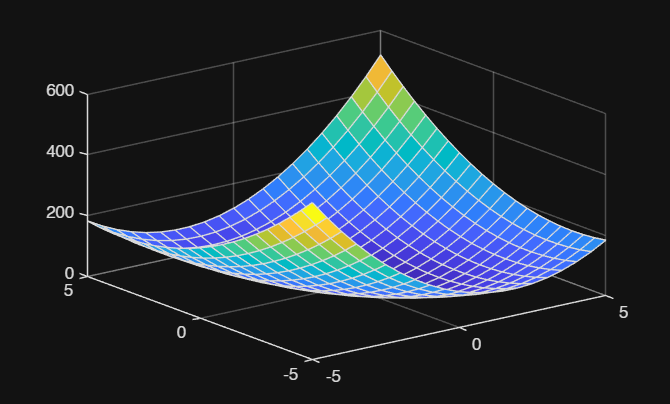

[x,y]=meshgrid(-5:0.5:5);
f=S(1,1)*x.^2+2*S(1,2)*x.*y+S(2,2)*y.^2;
surf(x,y,f)

*4. Using QR decomposition find the eigenvalues of the following matrices using 50 iterations in MATLAB. *

*(a) 4th order Pascal’s matrix *

A=pascal(4);
B=A;
for i=1:50
    [Q,R]=qr(B);
    B=R*Q;
end
diag(B)

ans =    26.3047
    2.2034
    0.4538
    0.0380


eig(A)

ans =     0.0380
    0.4538
    2.2034
   26.3047


(b) A=[ 1 2 1 ; 2 1 3 ; 5 7 0 ] 

A=[1 2 1; 2 1 3; 5 7 0];
B=A;
for i=1:50
    [Q,R]=qr(B);
    B=R*Q;
end
diag(B)

ans =     6.7166
   -4.0559
   -0.6607


eig(A)

ans =     6.7166
   -0.6607
   -4.0559


(c) B=[ 1 −1 0 0 ;  −1 2 −1 0 ; 0 −1 2 −1 ; 0 0 −1 2]

A=[1 -1 0 0 ;  -1 2 -1 0 ; 0 -1 2 -1 ; 0 0 -1 2];
B=A;
for i=1:50
    [Q,R]=qr(B);
    B=R*Q;
end

diag(B)

ans =     3.5321
    2.3473
    1.0000
    0.1206


eig(A)

ans =     0.1206
    1.0000
    2.3473
    3.5321


(d) a random 50 by 50 matrix  

A=randi([0,9],50,50);
B=A;
for i=1:50
    [Q,R]=qr(B);
    B=R*Q;
end
diag(B)

ans =   228.5256
   -9.1863
  -10.5138
   11.6267
    9.0137
   12.9442
   10.0300
   -9.8861
   -4.5575
   -6.8948
  -16.0292
  -13.9743
  -14.5659
   13.7499
    7.3142


eig(A)

ans = 1.0e+02 *

   2.2853 + 0.0000i
  -0.1458 + 0.1510i
  -0.1458 - 0.1510i
  -0.0605 + 0.1891i
  -0.0605 - 0.1891i
   0.1396 + 0.1535i
   0.1396 - 0.1535i
   0.1907 + 0.0618i
   0.1907 - 0.0618i
  -0.2047 + 0.0000i
  -0.1585 + 0.0991i
  -0.1585 - 0.0991i
  -0.0749 + 0.1407i
  -0.0749 - 0.1407i
  -0.1704 + 0.0000i


5. Find the polar decomposition of the matrix: 𝐴=[ 3 3  ; −1 1 ]. 

A=[3 3;-1 1]

A =      3     3
    -1     1


[U,Z,V]=svd(A);
Q=U*V';
S=V*Z*V';
disp(S);

    2.8284    1.4142
    1.4142    2.8284



check=Q*S

check =     3.0000    3.0000
   -1.0000    1.0000


*6. Generate a square matrix A of order 9 and rank 9. Find the polar decomposition A=QS of this matrix.  Verify that the matrix S is positive definite. *

A=randi([0,9],9,9);
[U,Z,V]=svd(A);
Q=U*V';
S=V*Z*V';
disp(S);

   10.3520    5.6081    5.1806    1.5180    1.2675    4.9236    3.8037    3.3594    1.6252
    5.6081   11.5774    6.8970    3.2599    7.1003    7.6977    7.3782    2.1403    2.5749
    5.1806    6.8970    9.1268    3.0596    2.8661    6.1257    5.5703    5.1150    5.2917
    1.5180    3.2599    3.0596   11.7416    4.3688    6.5943    3.1696    5.8939    6.4410
    1.2675    7.1003    2.8661    4.3688   10.1252    6.0305    5.6587    3.4540    2.4171
    4.9236    7.6977    6.1257    6.5943    6.0305    9.7767    6.0049    4.6872    3.5377
    3.8037    7.3782    5.5703    3.1696    5.6587    6.0049    9.7152   -0.4480    2.0870
    3.3594    2.1403    5.1150    5.8939    3.4540    4.6872   -0.4480   11.0487    4.2495
    1.6252    2.5749    5.2917    6.4410    2.4171    3.5377    2.0870    4.2495   10.3667



check=Q*S

check =     5.0000    6.0000    7.0000    2.0000    4.0000    5.0000    2.0000    8.0000    3.0000
    9.0000    9.0000    8.0000    4.0000    3.0000    7.0000    6.0000    4.0000    4.0000
    3.0000    4.0000    5.0000    8.0000    5.0000    7.0000    5.0000    7.0000    3.0000
    0.0000    9.0000    7.0000    6.0000    8.0000    7.0000    9.0000    1.0000    7.0000
    2.0000   -0.0000    3.0000    9.0000    1.0000    3.0000   -0.0000    6.0000    9.0000
    3.0000    6.0000    2.0000    2.0000    8.0000    4.0000    5.0000    2.0000    1.0000
    3.0000    8.0000    3.0000    8.0000    8.0000    9.0000    5.0000    4.0000    2.0000
    2.0000    2.0000    5.0000    6.0000    3.0000    5.0000   -0.0000    8.0000    7.0000
    9.0000    9.0000    8.0000    2.0000    4.0000    8.0000    9.0000    1.0000    3.0000


eigS=eig(S);
if all(eigS>0)
    disp("S is positive definite")
else
    disp("S is NOT Positive definite")
end

S is positive definite


*7. Generate a square matrix A of order 9 and rank 7. Find the polar decomposition A=QS of this matrix.  Verify that the matrix S is not positive definite but is positive semi-definite. *

A=randi([0,9],9,7)*randi([0,9],7,9);
rank(A)

ans = 7

[U,Z,V]=svd(A)

U =    -0.3476    0.6542   -0.2936    0.3088    0.1714   -0.0664    0.4725   -0.0411   -0.1047
   -0.3403   -0.0421   -0.2483   -0.1695   -0.0185    0.8476   -0.1614   -0.0677   -0.2063
   -0.2215    0.3736    0.3510   -0.0475   -0.3974    0.0990   -0.1713   -0.3586    0.6001
   -0.3955   -0.0731    0.5618    0.2339    0.2095    0.1304    0.0236    0.6311    0.0905
   -0.4289    0.1137   -0.3479   -0.2160    0.1776   -0.4007   -0.6399    0.1731    0.0618
   -0.2778   -0.0103    0.3201   -0.7479    0.1833   -0.1649    0.3445   -0.1924   -0.2107
   -0.2146   -0.3058    0.1712    0.3953    0.5153   -0.0421   -0.1382   -0.6229   -0.0212
   -0.3895   -0.2122    0.0855    0.2366   -0.6544   -0.2387   -0.0085   -0.0945   -0.4958
   -0.3146   -0.5232   -0.3915   -0.0260   -0.0980   -0.0611    0.4165    0.0536    0.5326


Z = 1.0e+03 *

    1.3999         0         0         0         0         0         0         0         0
         0    0.1684         0         0         0         0         0         0         0
         0         0    0.0607         0         0         0         0         0         0
         0         0         0    0.0430         0         0         0         0         0
         0         0         0         0    0.0297         0         0         0         0
         0         0         0         0         0    0.0175         0         0         0
         0         0         0         0         0         0    0.0030         0         0
         0         0         0         0         0         0         0    0.0000         0
         0         0         0         0         0         0         0         0    0.0000


V =    -0.3241   -0.1690   -0.4474   -0.5021   -0.2040   -0.4077    0.1277   -0.4327   -0.0515
   -0.3245    0.1959   -0.2144   -0.1688    0.3708    0.2233   -0.4806    0.1272   -0.5893
   -0.3021   -0.4628   -0.0198    0.3621    0.2059   -0.5168    0.1362    0.4566   -0.1628
   -0.3352    0.1725   -0.1103    0.0958   -0.8004    0.1400   -0.0934    0.4082   -0.0317
   -0.2922   -0.1728   -0.5222    0.1236    0.2638    0.4595    0.0812    0.0839    0.5500
   -0.3217    0.7370    0.1105   -0.0462    0.2439   -0.3714    0.1272    0.1255    0.3313
   -0.4363   -0.2671    0.5095    0.0106   -0.0354   -0.0187   -0.5471   -0.2733    0.3208
   -0.3028   -0.1532    0.4401   -0.4798    0.0792    0.3446    0.5321    0.1973   -0.1179
   -0.3394    0.1459    0.0560    0.5756   -0.0359    0.1706    0.3466   -0.5338   -0.3057


Q=U*V';
S=V*Z*V';
disp(S);

  179.0305  147.0861  145.4219  151.9111  144.1328  124.1860  191.6204  137.4102  135.0143
  147.0861  163.5310  119.6215  150.5822  137.4895  170.3880  183.0033  131.6810  153.8520
  145.4219  119.6215  175.4549  123.7360  137.0529   82.6312  204.5964  129.5668  139.4325
  151.9111  150.5822  123.7360  182.8344  130.9246  164.7041  194.5659  131.5227  166.6889
  144.1328  137.4895  137.0529  130.9246  147.4991  105.3326  169.5634  115.3143  137.0311
  124.1860  170.3880   82.6312  164.7041  105.3326  241.3908  166.3743  119.7741  168.9548
  191.6204  183.0033  204.5964  194.5659  169.5634  166.3743  295.2055  204.1367  202.1450
  137.4102  131.6810  129.5668  131.5227  115.3143  119.7741  204.1367  157.0654  131.2182
  135.0143  153.8520  139.4325  166.6889  137.0311  168.9548  202.1450  131.2182  180.2112



check=Q*S

check =   140.0000  182.0000  103.0000  181.0000  135.0000  237.0000  173.0000  117.0000  188.0000
  160.0000  161.0000  137.0000  162.0000  154.0000  141.0000  202.0000  147.0000  158.0000
   83.0000  105.0000   60.0000  122.0000   66.0000  145.0000  130.0000   94.0000  115.0000
  159.0000  171.0000  176.0000  176.0000  150.0000  173.0000  262.0000  181.0000  194.0000
  207.0000  206.0000  174.0000  201.0000  180.0000  209.0000  247.0000  171.0000  198.0000
  134.0000  128.0000  109.0000  120.0000  100.0000  130.0000  179.0000  142.0000  114.0000
   90.0000   88.0000  124.0000   80.0000   97.0000   63.0000  150.0000   96.0000  104.0000
  181.0000  159.0000  183.0000  192.0000  157.0000  146.0000  251.0000  165.0000  186.0000
  170.0000  129.0000  174.0000  137.0000  155.0000   74.0000  203.0000  137.0000  135.0000


eigS=eig(S)

eigS = 1.0e+03 *

    1.3999
    0.1684
    0.0607
    0.0430
    0.0297
    0.0175
    0.0030
   -0.0000
    0.0000


if all(eigS>0)
    disp("S in positive definite")
elseif all(eigS>=0)
    disp("S is Positive semi-definite")
else
    disp("S is Not positive semi-definite")
end

S is Not positive semi-definite


8. Find the pseudo inverse of A (in question 5, 6 and 7) and SVD of A.

%for question no 5
A=[3 3;-1 1];
psinv=pinv(A);
[U,Z,V]=svd(A);
pinvsvd=V*pinv(Z)*U';
disp(psinv);

    0.1667   -0.5000
    0.1667    0.5000



disp(pinvsvd);

    0.1667   -0.5000
    0.1667    0.5000



disp(norm(psinv - pinvsvd));

     0



%for question no 6
A=randi([0,9],9,9);
psinv=pinv(A);
[U,Z,V]=svd(A);
pinvsvd=V*pinv(Z)*U';
disp(psinv);

    0.0062    0.0312    0.0127   -0.0038    0.1311   -0.0746    0.0100   -0.0156   -0.0068
    0.0670   -0.0655   -0.1204   -0.0051    0.0780   -0.0164    0.0512   -0.0149    0.0454
    0.0351    0.2843    0.0662   -0.0971   -0.2055    0.2568   -0.1198    0.0571   -0.3170
   -0.0790   -0.1017   -0.0257    0.1396    0.1584   -0.0420    0.0521   -0.1166    0.1135
   -0.0963    0.0043   -0.0450   -0.0087    0.0401   -0.0852    0.0963    0.0424    0.0750
    0.0128    0.0284   -0.0269    0.0648   -0.1017    0.0627   -0.1072    0.0890   -0.0623
    0.0499    0.0313    0.1061   -0.0634   -0.2121    0.0443   -0.0021    0.1449   -0.1250
    0.0190    0.0080    0.1012   -0.0750   -0.0851    0.0705   -0.1055    0.0814   -0.0289
   -0.0009   -0.2433   -0.0328    0.0827    0.2389   -0.2462    0.1993   -0.2579    0.3915



disp(pinvsvd);

    0.0062    0.0312    0.0127   -0.0038    0.1311   -0.0746    0.0100   -0.0156   -0.0068
    0.0670   -0.0655   -0.1204   -0.0051    0.0780   -0.0164    0.0512   -0.0149    0.0454
    0.0351    0.2843    0.0662   -0.0971   -0.2055    0.2568   -0.1198    0.0571   -0.3170
   -0.0790   -0.1017   -0.0257    0.1396    0.1584   -0.0420    0.0521   -0.1166    0.1135
   -0.0963    0.0043   -0.0450   -0.0087    0.0401   -0.0852    0.0963    0.0424    0.0750
    0.0128    0.0284   -0.0269    0.0648   -0.1017    0.0627   -0.1072    0.0890   -0.0623
    0.0499    0.0313    0.1061   -0.0634   -0.2121    0.0443   -0.0021    0.1449   -0.1250
    0.0190    0.0080    0.1012   -0.0750   -0.0851    0.0705   -0.1055    0.0814   -0.0289
   -0.0009   -0.2433   -0.0328    0.0827    0.2389   -0.2462    0.1993   -0.2579    0.3915



disp(norm(psinv - pinvsvd));

   4.8101e-17



%for question no 7
A=randi([0,9],9,7)*randi([0,9],7,9);
psinv=pinv(A);
[U,Z,V]=svd(A);
pinvsvd=V*pinv(Z)*U';
disp(psinv);

    0.0274   -0.0007   -0.0083   -0.0039   -0.0077   -0.0121   -0.0380    0.0127    0.0134
   -0.0096    0.0060    0.0218   -0.0002   -0.0084    0.0157   -0.0063   -0.0001   -0.0091
    0.0346    0.0090   -0.0231   -0.0143   -0.0156    0.0030   -0.0573    0.0074    0.0288
    0.0072    0.0032   -0.0199   -0.0058    0.0043   -0.0117   -0.0024   -0.0013    0.0160
   -0.0452    0.0041    0.0139    0.0080    0.0131    0.0121    0.0366   -0.0111   -0.0112
    0.1048   -0.0063   -0.0384   -0.0209   -0.0271   -0.0453   -0.0550    0.0205    0.0275
   -0.0780   -0.0077    0.0152    0.0119    0.0500    0.0088    0.0723   -0.0205   -0.0195
   -0.0560    0.0048    0.0314    0.0088    0.0098    0.0338    0.0365   -0.0146   -0.0235
    0.0363   -0.0066    0.0121    0.0168   -0.0426    0.0035   -0.0157    0.0161   -0.0190



disp(pinvsvd);

    0.0274   -0.0007   -0.0083   -0.0039   -0.0077   -0.0121   -0.0380    0.0127    0.0134
   -0.0096    0.0060    0.0218   -0.0002   -0.0084    0.0157   -0.0063   -0.0001   -0.0091
    0.0346    0.0090   -0.0231   -0.0143   -0.0156    0.0030   -0.0573    0.0074    0.0288
    0.0072    0.0032   -0.0199   -0.0058    0.0043   -0.0117   -0.0024   -0.0013    0.0160
   -0.0452    0.0041    0.0139    0.0080    0.0131    0.0121    0.0366   -0.0111   -0.0112
    0.1048   -0.0063   -0.0384   -0.0209   -0.0271   -0.0453   -0.0550    0.0205    0.0275
   -0.0780   -0.0077    0.0152    0.0119    0.0500    0.0088    0.0723   -0.0205   -0.0195
   -0.0560    0.0048    0.0314    0.0088    0.0098    0.0338    0.0365   -0.0146   -0.0235
    0.0363   -0.0066    0.0121    0.0168   -0.0426    0.0035   -0.0157    0.0161   -0.0190



disp(norm(psinv - pinvsvd));

   1.9668e-17



*9. Generate a 5 by 3 matrix of rank 3. Using SVD find a basis for the left null space of the matrix and the null space of the matrix.*

A=randi([0,9],5,3)*randi([0,9],3,3);
r=rank(A)

r = 3

[U,Z,V]=svd(A);
NS=V(:,r+1:end);
LNS=U(:,r+1:end);
disp(NS);
disp(LNS);

   -0.5886   -0.5246
   -0.4543    0.7070
   -0.1200    0.0907
    0.6258   -0.1095
    0.2029    0.4526



%for verification :
norm(A*NS)<1e-10

ans = logical
   1


norm(A'*LNS)<1e-10

ans = logical
   1


*10. Generate a 6 by 5 matrix of rank 4. Using SVD find a basis for all the fundamental subspaces of matrix A *

A=randi([0,9],6,4)*randi([0,9],4,5);
r=rank(A)

r = 4

[U,Z,V]=svd(A);
CS=U(:,1:r);
RS=V(:,1:r);
NS=V(:,r+1:end);
LNS=U(:,r+1:end);
CS, RS, NS, LNS

CS =    -0.1591   -0.1783    0.0461    0.7762
   -0.5145   -0.4189    0.4218    0.1971
   -0.1422   -0.5218   -0.2607   -0.3933
   -0.3146   -0.1085    0.4908   -0.4492
   -0.6514    0.0983   -0.6740   -0.0144
   -0.4081    0.7064    0.2384   -0.0447


RS =    -0.3075    0.4003    0.5547    0.6471
   -0.4983    0.6100   -0.6002   -0.0750
   -0.3328   -0.0023    0.1788   -0.4774
   -0.3295    0.0718    0.5248   -0.5295
   -0.6617   -0.6801   -0.1570    0.2595


NS =    -0.1366
    0.1171
   -0.7934
    0.5749
    0.0880


LNS =     0.5803    0.0389
   -0.5745    0.1138
    0.3054    0.6258
    0.4739   -0.4711
   -0.0535   -0.3298
    0.1116    0.5130


%verification
norm(RS'*NS)<1e-10

ans = logical
   1


norm(CS'*LNS)<1e-10

ans = logical
   1


*11. Solve 9x-2y+3z =1, 4x+9y-5z=3, 6x-y-z=3; using LU decomposition. *

A=[9 -2 3;
    4 9 -5;
    6 -1 -1];
B=[1;3;3];
[L,U]=lu(A);
Y=L\B; %solving LY=B forward substitution
X=U\Y; %solving UX=Y back substitution
disp("Solution [x y z] = "),disp(X);

Solution [x y z] = 
    0.3226
   -0.2581
   -0.8065



*12. Express the Pascal matrix of order 7 as LU using elementary matrices, by reducing it to upper triangular form manually.*

A=pascal(7);
[L,U]=lu(A);
disp("L ="),disp(L);

L =
    1.0000         0         0         0         0         0         0
    1.0000    0.1667    0.5556   -1.0000    1.0000         0         0
    1.0000    0.3333    0.8889   -0.8000    0.6000   -1.0000    1.0000
    1.0000    0.5000    1.0000         0         0         0         0
    1.0000    0.6667    0.8889    0.8000   -0.2000    1.0000         0
    1.0000    0.8333    0.5556    1.0000         0         0         0
    1.0000    1.0000         0         0         0         0         0



disp("U ="),disp(U);

U =
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
         0    6.0000   27.0000   83.0000  209.0000  461.0000  923.0000
         0         0   -4.5000  -22.5000  -70.5000 -175.5000 -378.5000
         0         0         0   -1.6667  -10.0000  -35.6667  -97.8889
         0         0         0         0   -1.6667  -10.0000  -35.4444
         0         0         0         0         0    0.2000    1.3333
         0         0         0         0         0         0    0.0667



%for verification 
norm(A-L*U)<1e-10

ans = logical
   1


U=A;
n=size(A,1);
L=eye(n);
for k=1:n-1
    for i=k+1:n
        m=U(i,k)/U(k,k);
        U(i,:)=U(i,:)-m*U(k,:);
        L(i,k)=m;
    end
end

disp("L ="),disp(L);

L =
     1     0     0     0     0     0     0
     1     1     0     0     0     0     0
     1     2     1     0     0     0     0
     1     3     3     1     0     0     0
     1     4     6     4     1     0     0
     1     5    10    10     5     1     0
     1     6    15    20    15     6     1



disp("U ="),disp(U);

U =
     1     1     1     1     1     1     1
     0     1     2     3     4     5     6
     0     0     1     3     6    10    15
     0     0     0     1     4    10    20
     0     0     0     0     1     5    15
     0     0     0     0     0     1     6
     0     0     0     0     0     0     1



norm(A-L*U)

ans = 0

%another method
[Pmat,L,U]=lu(A);
norm(A - L*U)<1e-10

ans = logical
   0
